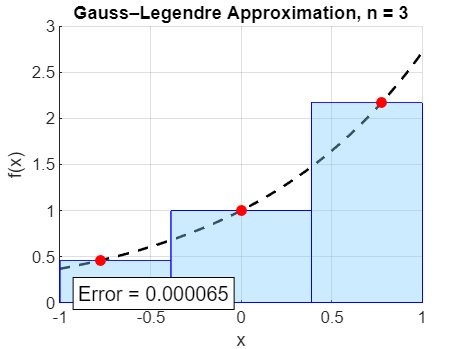

clc; clear;

% Define function to integrate
f = @(x) exp(x);  % You can change this to any smooth function

% Domain
a = -1; b = 1;

% Exact integration
I_exact = integral(f, a, b, 'AbsTol', 1e-12, 'RelTol', 1e-12);

% Animation loop over n
for n = 1:3
    % Get Gauss–Legendre points and weights
    [xi, w] = lgwt(n, a, b);
    xi = flip(xi);  % Optional: left-to-right orientation
    fi = f(xi);

    % Plot setup
    figure(1); clf; hold on; grid on;
    fplot(f, [a, b], 'k--', 'LineWidth', 1.5);
    xlabel('x'); ylabel('f(x)');
    title(['Gauss–Legendre Approximation, n = ', num2str(n)]);

    % Draw rectangles
    for i = 1:n
        % Rectangle boundaries
        if i == 1
            x_left = a;
        else
            x_left = (xi(i-1) + xi(i)) / 2;
        end
        if i == n
            x_right = b;
        else
            x_right = (xi(i) + xi(i+1)) / 2;
        end
        width = x_right - x_left;

        % Rectangle shape
        x_rect = [x_left, x_right, x_right, x_left];
        y_rect = [0, 0, fi(i), fi(i)];

        % Draw
        fill(x_rect, y_rect, [0.5 0.8 1], 'EdgeColor', 'b', 'FaceAlpha', 0.4);
        plot(xi(i), fi(i), 'ro', 'MarkerFaceColor', 'r');
    end

    % Compute and display integral
    I_approx = sum(w .* fi);
    text(a + 0.1, 0.1, sprintf('Error = %.6f', abs(I_approx-I_exact)), ...
        'FontSize', 12, 'BackgroundColor', 'w', 'EdgeColor', 'k');

    pause(1.2);  % Wait before updating for next n
end